convoluzione diretta

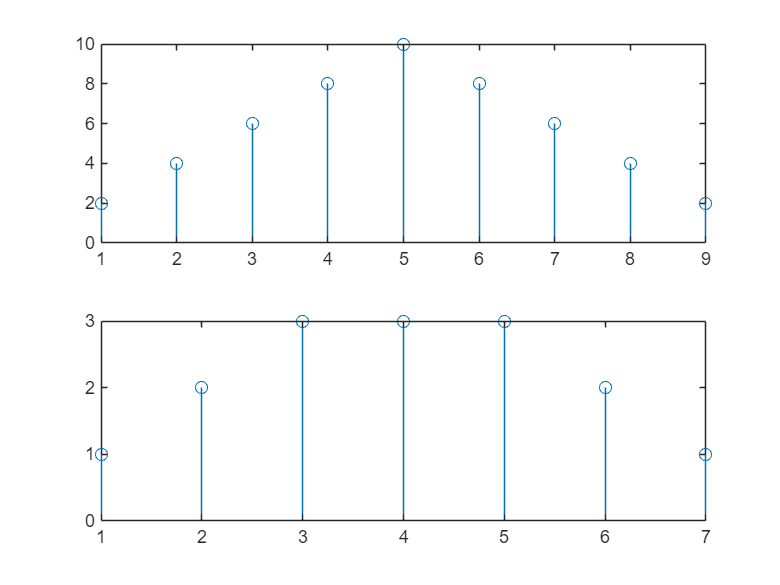

x1 = [1 1 1 1 1];
x2 = [2 2 2 2 2];
x3 = [1 1 1];
y1 = conv(x1,x2);
y2 = conv(x1,x3);
figure(1)
subplot(211)
stem(y1)
subplot(212)
stem(y2)

convoluzione matriciale

x = (1:5)';
h = [1 1 2 -1]';
c = [x; zeros(length(h)-1,1)];
r = [x(1) zeros(1,length(h)-1)];
X = toeplitz(c,r)

X =      1     0     0     0
     2     1     0     0
     3     2     1     0
     4     3     2     1
     5     4     3     2
     0     5     4     3
     0     0     5     4
     0     0     0     5


y1 = conv(x,h)'

y1 =      1     3     7    10    13    10     6    -5


y2 = (X*h)'

y2 =      1     3     7    10    13    10     6    -5


l'equazione delle differenze

x = [3 -1 2 4 0 -3 -5 1];
b = [1 1];
a = [1 -2 3];
zi = filtic(b,a,0)

zi =      0     0


[y,zf] = filter(b,a,x,zi)

y =      3     8     8    -2   -24   -45   -26    79


zf =    237
  -237


poli,zeri,risposta impulsiva

b = [1 -2 3];
a = [1 0 1/2 2/5 -1/7];
roots(b)

ans =    1.0000 + 1.4142i
   1.0000 - 1.4142i


roots(a)

ans =    0.1994 + 0.8895i
   0.1994 - 0.8895i
  -0.6595 + 0.0000i
   0.2607 + 0.0000i


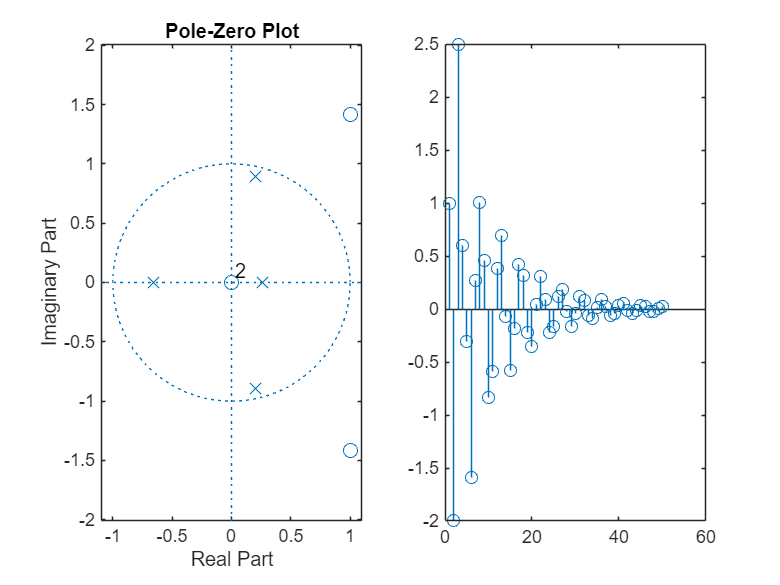

subplot(121)
zplane(b,a)
subplot(122)
stem(impz(b,a,50))

risposta in frequenza

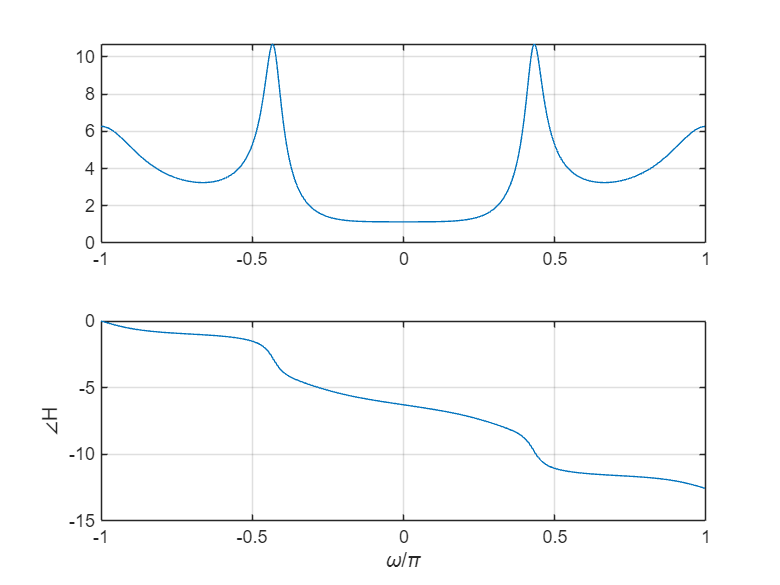

b = [1 -2 3];
a = [1 0 1/2 2/5 -1/7];
[H,w] = freqz(b, a, 512, "whole");
subplot(211)
plot(w/pi-1,fftshift(abs(H)))
grid;xlim([-1 1])
subplot(212)
plot(w/pi-1,unwrap(angle(fftshift(H))))
grid;xlim([-1 1])
xlabel("\omega/\pi");ylabel("\angleH")